clear all;

path_opt_table= readtable('traj_opt.csv');

s_opt_table= readtable('length_opt.csv');


london_outer_table=readtable('london_outer.csv');

london_inner_table=readtable('london_inner.csv');


xy_ref= [path_opt_table.x_Traj_x, path_opt_table.traj_y];
s_ref= s_opt_table.x_S_opt;

u_steer= deg2rad([-15:1:15]);
dt= 0.1;
state_init= [xy_ref(1, 1); xy_ref(1,2) ; 0; 0];
run_length=940;

u_hist= [];
states_hist=[];

for i= 2:run_length
    ds= s_ref(i);
    state0= state_init;
    
    ref_devi= (xy_ref(i,2)- xy_ref(i-1,2))/(xy_ref(i,1)- xy_ref(i-1,1));
    devi_err_list=[];
    
    % generate path for each steer angle
    for j= 1:length(u_steer)
        
        [states_end, path_info, u]= SteerPathGenerator(state_init, dt, u_steer(j), ds);
        
        path_devi= (states_end(end, 2)- state0(2))/((states_end(end,1)- state0(1)));
        devi_err= abs(path_devi- ref_devi);
        devi_err_list= [devi_err_list; devi_err];
    end
    
    path_index= find(devi_err_list== min(devi_err_list));
    [states_passed, path_info_paseed, u_passed]= SteerPathGenerator(state0, dt, u_steer(path_index), ds);
    u_hist= [u_hist; u_passed];
    states_hist= [states_hist; states_passed];
    
    state_init= states_passed(end,:);
end


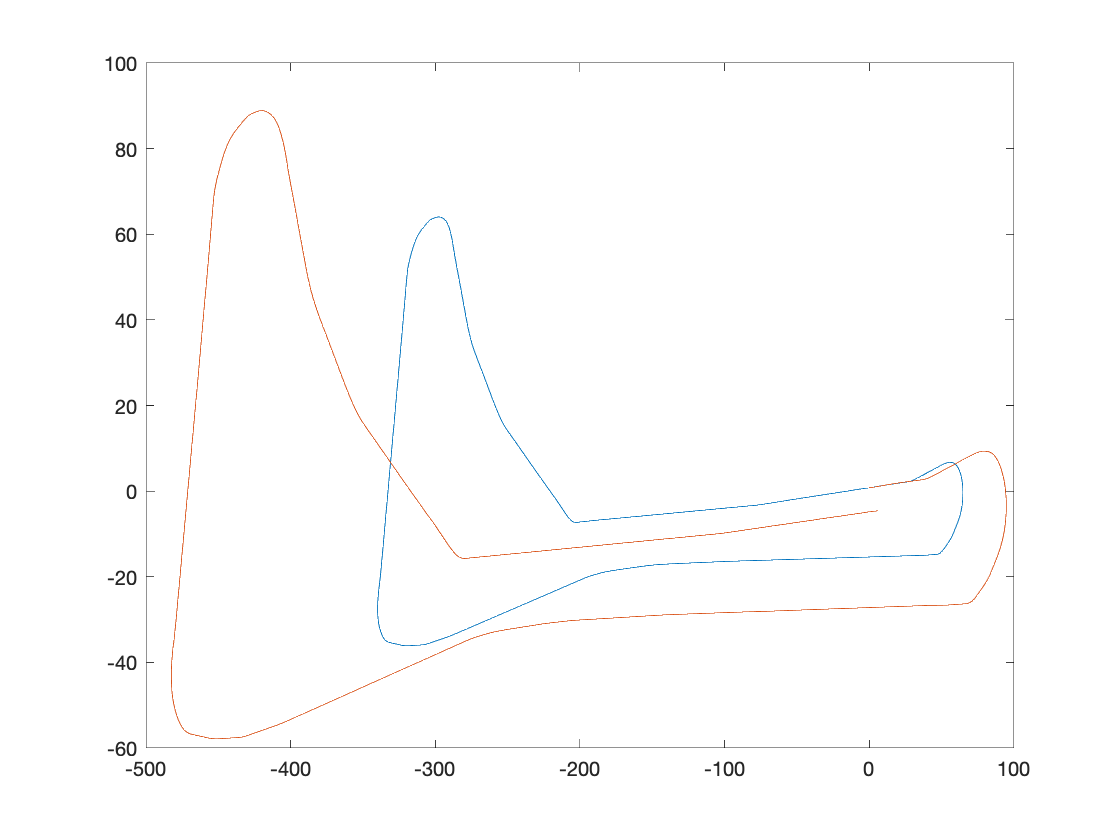

% path
plot_num= 1:run_length;
figure();
plot(xy_ref(plot_num, 1), xy_ref(plot_num, 2));
hold on;
plot(states_hist(:,1), states_hist(:,2));
hold off

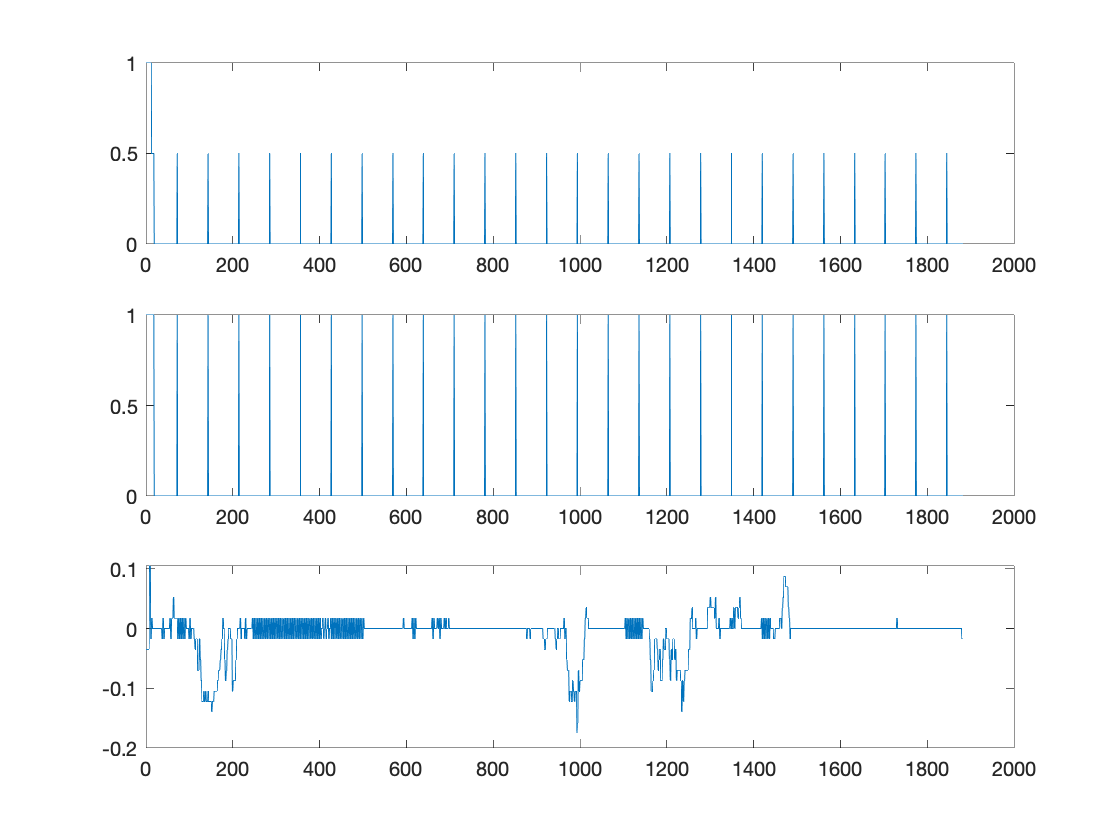


% inputs
figure();
subplot(3,1,1)
plot(u_hist(:,1));

subplot(3,1,2);
plot(u_hist(:,2));

subplot(3,1,3);
plot(u_hist(:,3));

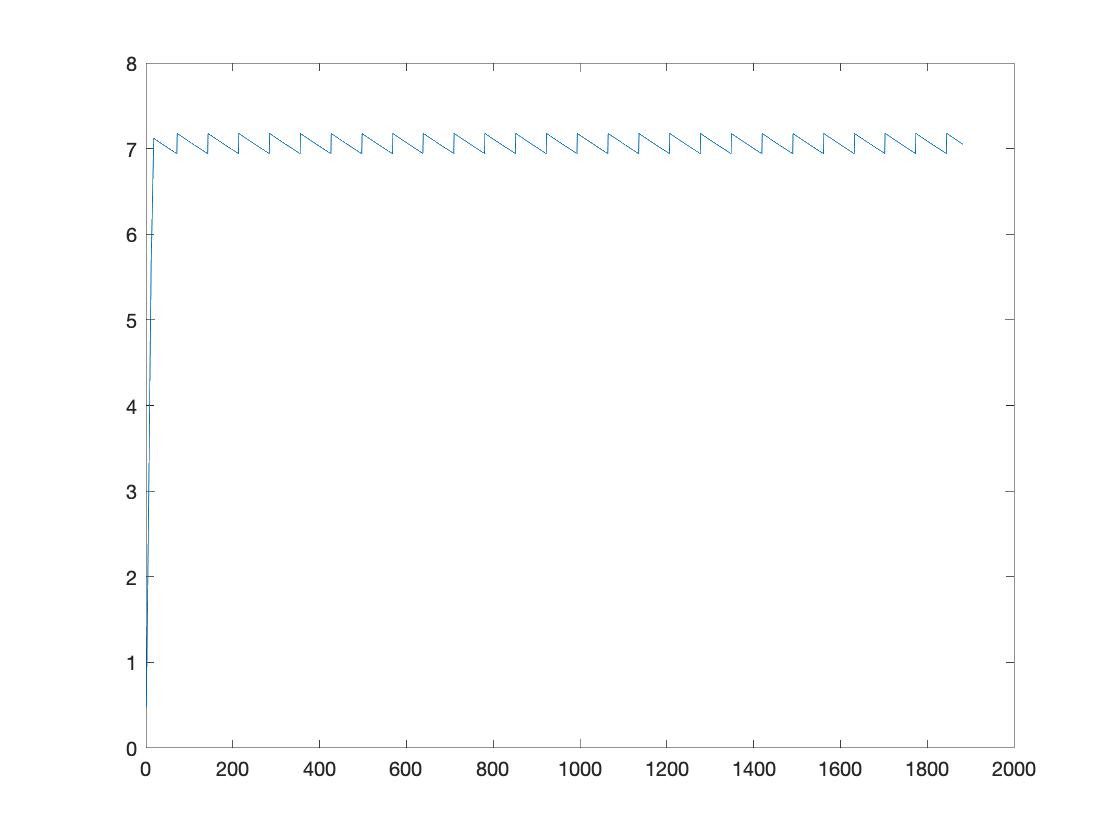


% speed
figure();
plot(states_hist(:,4));